#     Landmark localization 2d

Simulation of a robot moving in a 2d plane. Measurements are taken by beacons ( which transmit the range back to the robot ) and other sensors.

Date Started : 13 Dec. 2023 , 4: 30 PM

Author : Giorgio Ridolfi

## Sources in consultation order

1) [https://stackoverflow.com/questions/39818915/matlab-how-to-get-the-specs-of-the-host-machine](https://stackoverflow.com/questions/39818915/matlab-how-to-get-the-specs-of-the-host-machine)

2) [https://undocumentedmatlab.com/](https://undocumentedmatlab.com/)

3) Ristic, Branko, Sanjeev Arulampalam, and Neil Gordon. Beyond the Kalman filter: Particle filters for tracking applications. Artech house, 2003.

4) [https://it.mathworks.com/help/matlab/ref/plot3.html#f30-448776_sep_mw_3a76f056-2882-44d7-8e73-c695c0c54ca8](https://it.mathworks.com/help/matlab/ref/plot3.html#f30-448776_sep_mw_3a76f056-2882-44d7-8e73-c695c0c54ca8)

5) Groves, P. D. (2015). Principles of GNSS, inertial, and multisensor integrated navigation systems, [Book review]. *IEEE Aerospace and Electronic Systems Magazine*, *30*(2), 26-27.

6) [https://www.youtube.com/watch?v=5Pu558YtjYM&list=PLgnQpQtFTOGQrZ4O5QzbIHgl3b1JHimN_&index=4](https://www.youtube.com/watch?v=5Pu558YtjYM&list=PLgnQpQtFTOGQrZ4O5QzbIHgl3b1JHimN_&index=4)

## System Info

close all
clc
display("OS : " + computer("arch") + ", " + feature('GetOS') )

    "OS : win64, Microsoft Windows 11 Pro N"



display("Processor : " + feature('GetCPU') + ", " + feature('numCores') )

    "Processor : Intel(R) Core(TM) i5-8600K CPU @ 3.60GHz, 6"



% GPU = gpuDevice
clear all


## Generation of poses

We first generate a set of desired poses. From these, we create noisy system inputs to feed our robot by adding gaussian noise to the true inputs. This account for imperfections in the robot's movement. Then we calculate the poses that the robot achieves

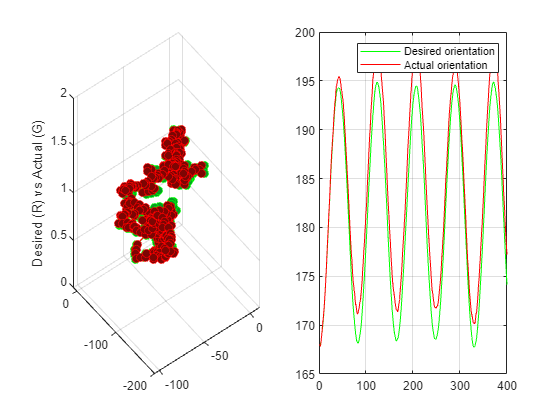

N_poses = 400;
poses = zeros(3,N_poses+1); % x_meters y_meters theta_radians
pose_0 = [ randi(10) ; randi(10) ; randi([0 360])  ];
poses(:,1) = pose_0;
u_odm = zeros(3,N_poses); 
real_poses = zeros(3,N_poses+1); 
real_poses( : , 1 ) = pose_0;

% Random walk params
stdx = 3;
stdy = 5;
psi_max = 6; % Degrees

stdtr = 0.1;
stdrot = 0.08726646255  ; % 0.01745329251*5


for i = 1 : N_poses

 x_incr = stdx*randn() ;
 y_incr = stdy*randn();
 psi_incr = sin(i*0.076) + 0.01745329251*randi([-psi_max psi_max]);

 poses(:,i+1) = poses(:,i) +  [ x_incr ; y_incr ; psi_incr ] ; 

 transl = sqrt( x_incr*x_incr + y_incr*y_incr ) ;
 rot1 = atan2(y_incr,x_incr) ;
 rot2 = poses(3,i+1) - poses(3,i) - rot1 ;
 
 u_odm(:,i) = [ transl + stdtr*randn()  ; rot1  + stdrot*randn() ; rot2 + stdrot*randn()   ];


 real_poses(3,i+1) = real_poses(3,i) + u_odm(2,i);
 real_poses(1,i+1) = real_poses(1,i) + u_odm(1,i)*cos( u_odm(2,i) );
 real_poses(2,i+1) = real_poses(2,i) + u_odm(1,i)*sin( u_odm(2,i) );
 real_poses(3,i+1) = real_poses(3,i+1) + u_odm(3,i) ;

end


figure
subplot(1,2,1);
plot3( poses(1,:), poses(2,:) , ones(1,N_poses+1) , '-o','Color','green','MarkerSize',6,'MarkerFaceColor','#049E22')
hold on
grid on
plot3(real_poses(1,:) , real_poses(2,:) , ones(1,N_poses+1) , '-o','Color','r','MarkerSize',6, 'MarkerFaceColor','#7D0503' )
zlabel("Desired (R) vs Actual (G)")

subplot(1,2,2);
plot(poses(3,:) , 'green' )
hold on
plot(real_poses(3,:) ,'red' )
grid on
legend("Desired orientation" , "Actual orientation")

The robot achieves the poses through a reasonably smooth trajectory. First, upsample.

N_up = 100;
dT = 1/N_up;
poses_up = zeros(3,N_up*N_poses);
slider = 0;
for i = 1 : N_poses
    for j = 1 : N_up
        alpha = j/N_up; 
        poses_up(:,j+slider) = (1-alpha)*real_poses(:,i) + (alpha)*real_poses(:,i+1);
    end
    slider = slider + 100;
end

figure
subplot(1,2,1);
plot3( poses_up(1,:), poses_up(2,:) , ones(1,N_up*N_poses) , '-o','Color','green','MarkerSize',2,'MarkerFaceColor','#049E22')
grid on
zlabel("Upsampled trajectory")
hold on

The trajectory will still look reasonably choppy, so we smooth it.

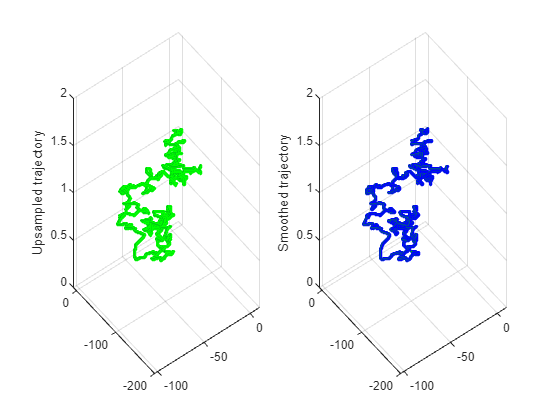

poses_up = kolmogorovZurbenkoFilter( poses_up , 35 , 3 , 1) ;
subplot(1,2,2);
plot3( poses_up(1,:), poses_up(2,:) , ones(1,N_up*N_poses) , '-o','Color','blue','MarkerSize',2,'MarkerFaceColor','#049E22')
grid on
zlabel( "Smoothed trajectory")


clear N_poses poses real_poses stdx stdy psi_max x_incr y_incr psi_incr i transl rot1 rot2 slider alpha j N_up

N = length(poses_up);

## Generation of a groundtruth

State space of the robot will be x y psi vx vy wpsi.

C_b_i = zeros(2,2,N);
for i = 1 : N
    psi = poses_up(3,i);
    cpsi = cos(psi);
    spsi = sin(psi);
    C_b_i( :,:,i ) = [cpsi , spsi; spsi, cpsi];
end
I2 = eye(2);
wpsi = zeros(2,2,N);
for i = 2 : N
    C_1 = C_b_i( :,:,i-1 ) ;
    C_2 = C_b_i( :,:,i ) ;
    wpsi(i) = A*( I2- (C_1')*C_2 )/dT;
end

Unable to perform assignment because the left and right sides have a different number of elements.

## Creation of arena

Generate a visual representation of the robot's trajectory

% 
% 
% A = [ abs(poses(1,:)) ; abs(poses(2,:)) ; abs(real_poses(1,:)) ; abs(real_poses(2,:)) ];
% dim_bound = ceil(max( A , [] , 'all' ));
% x_bounds = [-dim_bound:1:dim_bound];
% y_bounds = [-dim_bound:1:dim_bound];
% index = length(x_bounds);
% z_surf = ones(index);
% 
% figure
% surf(x_bounds,y_bounds,z_surf,"FaceColor","#9B9B9B")
% hold on
% plot3(real_poses(1,1) , real_poses(2,1) , 1 , '-o','Color','green','MarkerSize',8, 'MarkerFaceColor','#8EE67F' )
% plot3(real_poses(1,N_poses+1) , real_poses(2,N_poses+1) , 1 , '-o','Color','#64FFFD','MarkerSize',8, 'MarkerFaceColor','#1BEDEA' )
% plot3(real_poses(1,:) , real_poses(2,:) , ones(1,N_poses+1) , '-o','Color','r','MarkerSize',6, 'MarkerFaceColor','#7D0503' )
% legend("Arena" , "Start" ,"Finish", "Robot trajectory" )
% 
% clear x_incr y_incr th_incr transl rot1 rot2 A dim_bound i  poses stdx stdy th_max 
% 
% 
% 

## Creation of landmarks

These landmarks transmit range and bearing back to the robot

% num_landmarks = 4;
% coord_landmarks = zeros(3, num_landmarks);
% for i = 1 : num_landmarks
%     x_lm = randi(index);
%     y_lm = randi(index);
%     coord_landmarks(:,i) = [x_bounds(x_lm) ; y_bounds(y_lm) ; z_surf(y_lm , x_lm)];
% end
% scatter3(coord_landmarks(1,:) , coord_landmarks(2,:) , coord_landmarks(3,:) , 80 , 'b' , 'filled' , 'v' , 'MarkerEdgeColor','flat' , 'MarkerFaceColor','flat') 
% legend("Arena" , "Start" ,"Finish", "Robot trajectory","Landmarks"  )
% 
% clear x_lm y_lm x_bounds y_bounds index  z_surf 
% 
% coord_landmarks
% 

## APPENDIX : Functions

% function [ranges_out , bearings_out ] = hRadar(x_in , lm_coords)
% % Usage : pass an xyz position and obtain a number of measurements
% % corresponding to the 2*length(lm_coords) , representing range and bearing
% % of every landmark wrt to current robot position
% sizes_lm = size(lm_coords);
% num_lm = sizes_lm(1);
% 
% 
% 
% end
